# Chapter 4. LM317 DC power supply

(C) B. Rasnow 31May25

## Objective

Design and build an adjustable DC power supply (that's linear with potentiometer R2). 

## Background

In the previous chapter, we measured the I-V characteristic curves of an LED by varying a 10k pot in series with our 12VDC power supply and a fixed resistor (Fig. 1). 

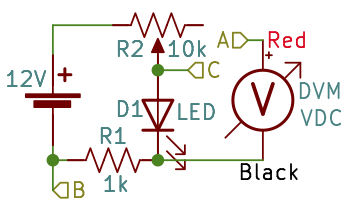

        Figure 1. Circuit used to measure LED's I-V curve.

We conceptualized this circuit as a voltage divider, and modeled it according to output VR1 = $(12.2V-V_f) * R1 / (R1+ R2)$, where R2 is the (variable) resistance of one the side of R2 in the series circuit. We saw one key weakness of the voltage divider as a power supply is its output is highly nonlinear with R2's value (because R2 appears in the denominator above). Another key weaknesses of a voltage divider as a variable DC voltage or current source is that it's $R_{Thevenin}$ = R1 || R2 is either high, or the power supply wastes a lot of power, $P = V_{Thevenin}^2/(R1+R2)$. 

**Assessment: **Prove those two equations and discuss their significance.

We can easily make a much better power supply, i.e., more efficient and low $R_{Thevenin}$, so its voltage changes very little when its load or current changes, using an integrated circuit (IC) called the LM317. Google "LM317 datasheet" (hint -- look for .pdf in the URLs) will reveal several documents describing this IC. Data sheets can be hard to read, but this (famous) chip also has it's own [Wikipedia page](https://en.wikipedia.org/wiki/LM317), [https://en.wikipedia.org/wiki/LM317](https://en.wikipedia.org/wiki/LM317.) that adds history, context, and the most commonly sought specifications. Historical detour: the LM317 was designed in 1976 by Bob Pease, who's also written many insightful articles and books, such as this one that I recommend after you've completed this class and read Art of Electronics (AoE): 

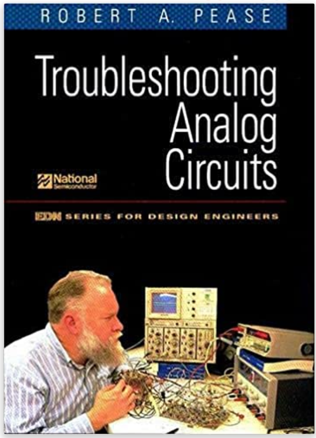

        Figure 2. Bob Pease, the inventor of the LM317, wrote some excellent (advanced) articles and books. 

    The LM317 continues to be a popular power supply IC, although much more efficient power supply ICs exist now. If you're building a device that may be in millions of consumers homes always turned on, then consider using a more efficient device. But if you use your power supply for 10 hours/week (right??), and let's estimate it wastes ~10mA (easy enough to measure) at ~12V, then over the semester it will have consumed _________ watt-hours of electricity, which at ~$.25/kWh would cost _______ . 

One of the simpler datasheets I found is [https://www.st.com/resource/en/datasheet/lm317.pdf](https://www.st.com/resource/en/datasheet/lm317.pdf) and here are some key points: 

- Page 0 (cover page): Features: .1% regulation means fluctuations in the input are attenuated (reduced) by 0.1% (1000 times smaller); internal protections means its pretty hard (but not impossible) to destroy this device -- it shuts off before fatally overheating; "monolithic" means it is built from a single piece of silicon, making it inexpensive.

- Section 1: The pin configuration is not what I would consider "logical" -- i.e., input is NOT on the left and output is NOT on the right. It is what it is ... always check (and double-check), always make sure you're not confusing a top view with a bottom view. It is possible to burn out LM317's by disrespecting their pinouts. Also the IC is available in different packages, ours is a TO-220 variant. 

- Section 3: The schematic diagram of this IC contains >~50 different resistors, transistors, diodes, capacitors!! But all that complexity is permanently "under the hood", we can't access it other than through it's 3 pins (right side). 

- Sections 4-5 list and graph electrical characteristics (minimum, typical, and maximum values). I tend to look for parameters of interest by scanning the far right column for the units I'm looking for, and when I find a row with those units, look to the left. Likewise, I look at the graph axes labels first -- I find that quicker than reading their titles. 

- Figure 6: The first schematic diagram is often the simplest circuit to use (test) the IC, and it's followed by what we might call the characteristic equation that describes the circuit's operation, both copied in Fig. 3:				

         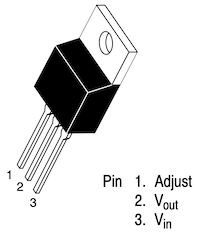  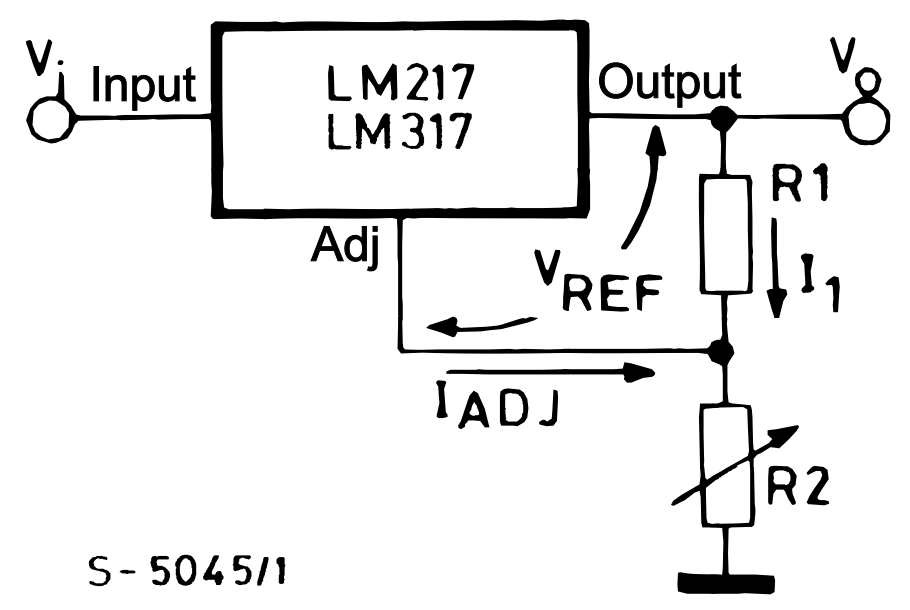 

            
$$V_0 = V_{REF} (1 + R2/R1) + I_{ADJ} R2$$
 

        Figure 3. The LM317 pinout (left) and basic circuit (right). It's characteristic equation relates Vout to the parameters identified in the circuit.

Note that Fig. 1 and Fig. 3 are totally independent circuits with different resistors that have the same names, R1 &R2. How many unknowns are there in this equation? ___________ 

You've learned in math classes that to solve an algebra problem, you need as many equations as there are unknowns. And you've learned to simplify algebra by substitution, cancellation, etc. In engineering (and physics), we often don't religiously simplify expressions because we want to understand how the variables and parameters relate to each other. Let's look for more equations. What is $V_{REF}$? Searching the data sheet for VREF takes me to page 5, a reference voltage typically 1.25V. So that's a 2nd equation. Searching for IADJ also lands on page 5, typically 50-100uA, and on page 10, right after the characteristic equation, they suggest, "Usually, the error term IADJ × R2 can be neglected." I generally think that neglect is a good place to start! (But bookmark it in your mind, because *neglect* can sometimes come back and bite you). Figure 7 suggests numerical values for R1 and R2, 240$\Omega$ and 5k respectively. We don't have those values, so let's simulate the equation with the closest ones we have. And since R2 is a variable resistor, which values should we use? With MATLAB, we can solve for an array of values just as easily as for one: 

### First LM317 Model

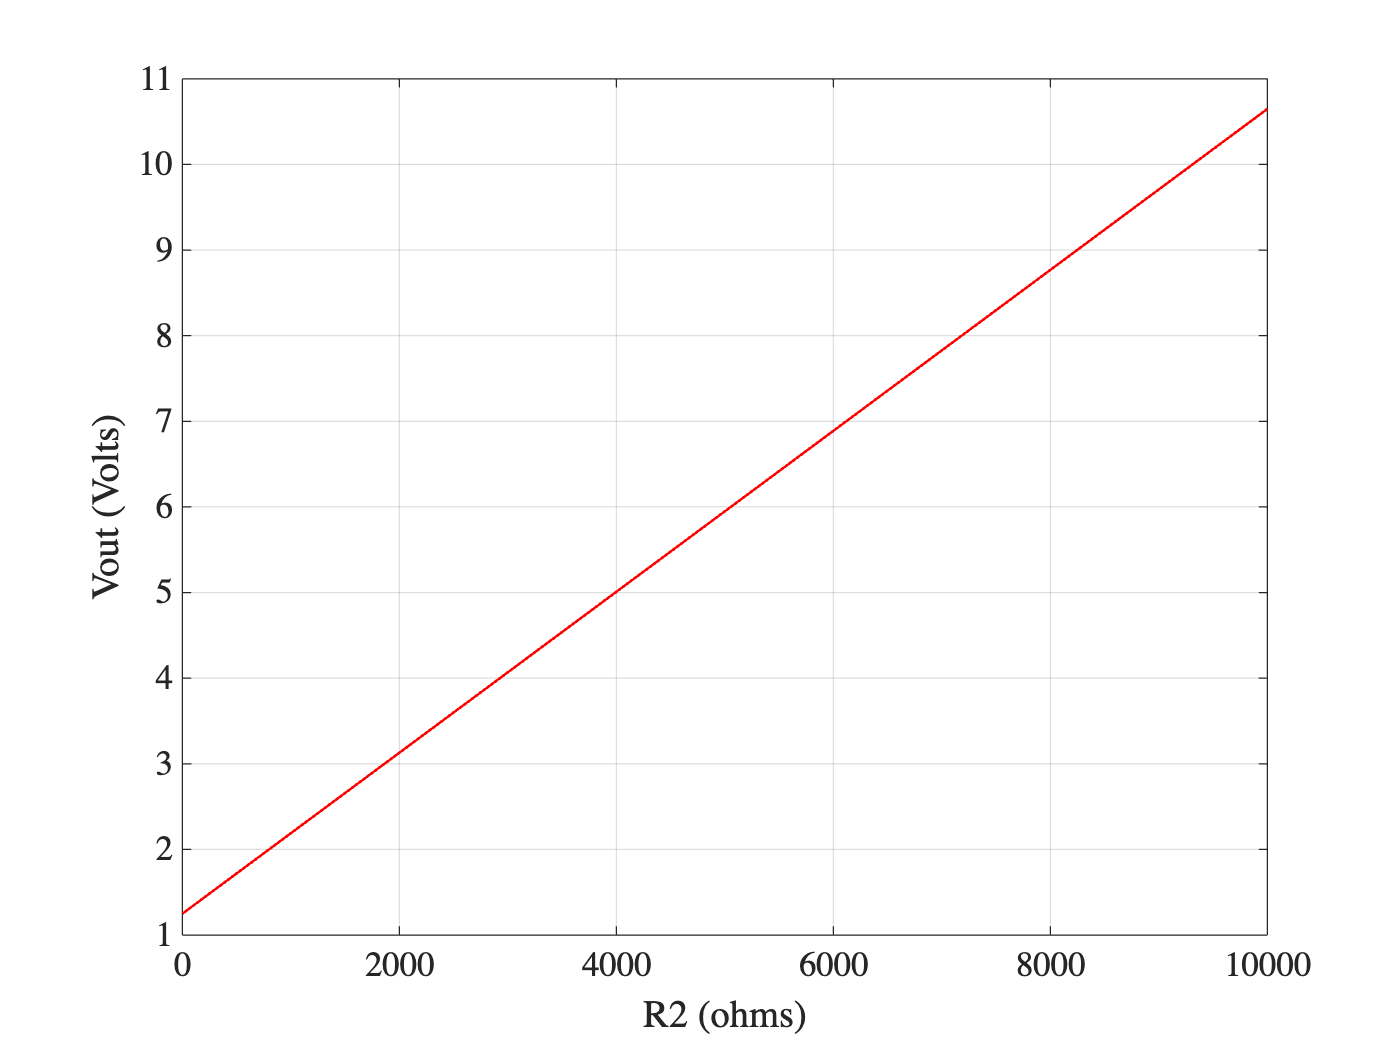

R1 = 1330; % ohms from Figure 7 of datasheet
R2 = linspace(0,10e3)'; % ohms -- variable resistor measured
VREF = 1.25; % volts
Vout = VREF * (1 + R2 / R1); % neglecting iAdjR2 term
plot(R2, Vout);
grid;
xlabel('R2 (ohms)');
ylabel('Vout (Volts)');

        Figure 4. Output voltage vs. value of R2 as predicted by the characteristic equation in the data sheet.

Is this the behavior we can expect? We could easily built the circuit and find out, but I'll give you the quick answer and save us a revision cycle. The model and circuit agree below ~11V, but not above. The LM317 can't put out more voltage than its input (more accurately, more than the input minus a "dropout voltage" ~1.5V according to Fig. 4 of the datasheet. Let's fix the model:

### Second LM317 model

 Measure `Vin` for your "wall wart" power supply. We can modify the model to "clip" the voltage or "saturate" using this code:

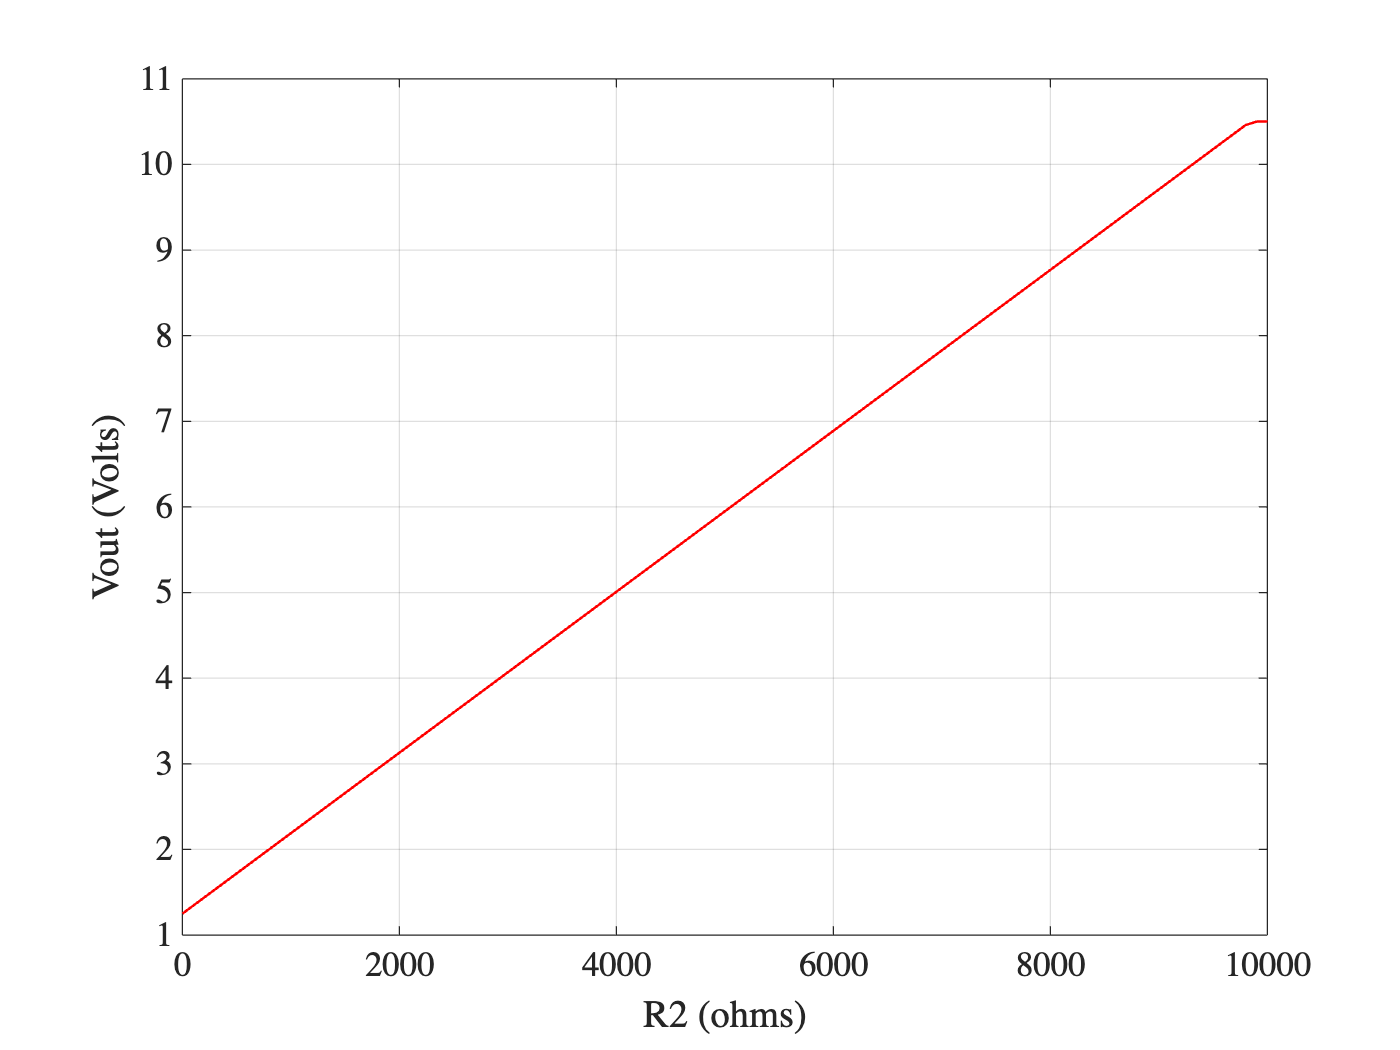

Vin = 12; % Vthevenin measured from the wall wart
Vdropout = 1.5; % volts from datasheet Figure 4
Vmax = Vin - Vdropout; 
Vout(Vout>Vmax) = Vmax;
plot(R2, Vout);
grid; xlabel('R2 (ohms)'); ylabel('Vout (Volts)');

        Figure 5. Output voltage vs. value of R2 modeled with clipping.

Note *how* we implemented the "clipping". `Vout>Vmax` is a 100 element Boolean array specifying which elements of `Vout` to change to `Vmax`. Fig. 5 should agree with the circuit's behavior -- the minimum voltage is 1.25V, and rotating the potentiometer rapidly (but linearly) increases the voltage to a saturation level around 11V. But this is a lousy design, because most of R2's upper range is useless -- it doesn't change `Vout`. How should we fix it? An obvious solution could be using a smaller value of R2 $\le$ 2k, but we only have 10k pots in our kits. 

### LM317 Design

Design an LM317 power supply with R2 = 10k pot, and find the value of an optimal R1 such that the slope intersects intersects with `Vmax` just before the maximum of R2 (as in Fig. 6). You could do this by algebraically manipulating the characteristic equation (in Fig. 3), but perhaps a much easier approach is trial and error. Iteratively tweak the value of R1 above and rerun the simulation (click the "Run" button in the Live Editor top taskbar) until you get close to the desired result (Fig. 6). 

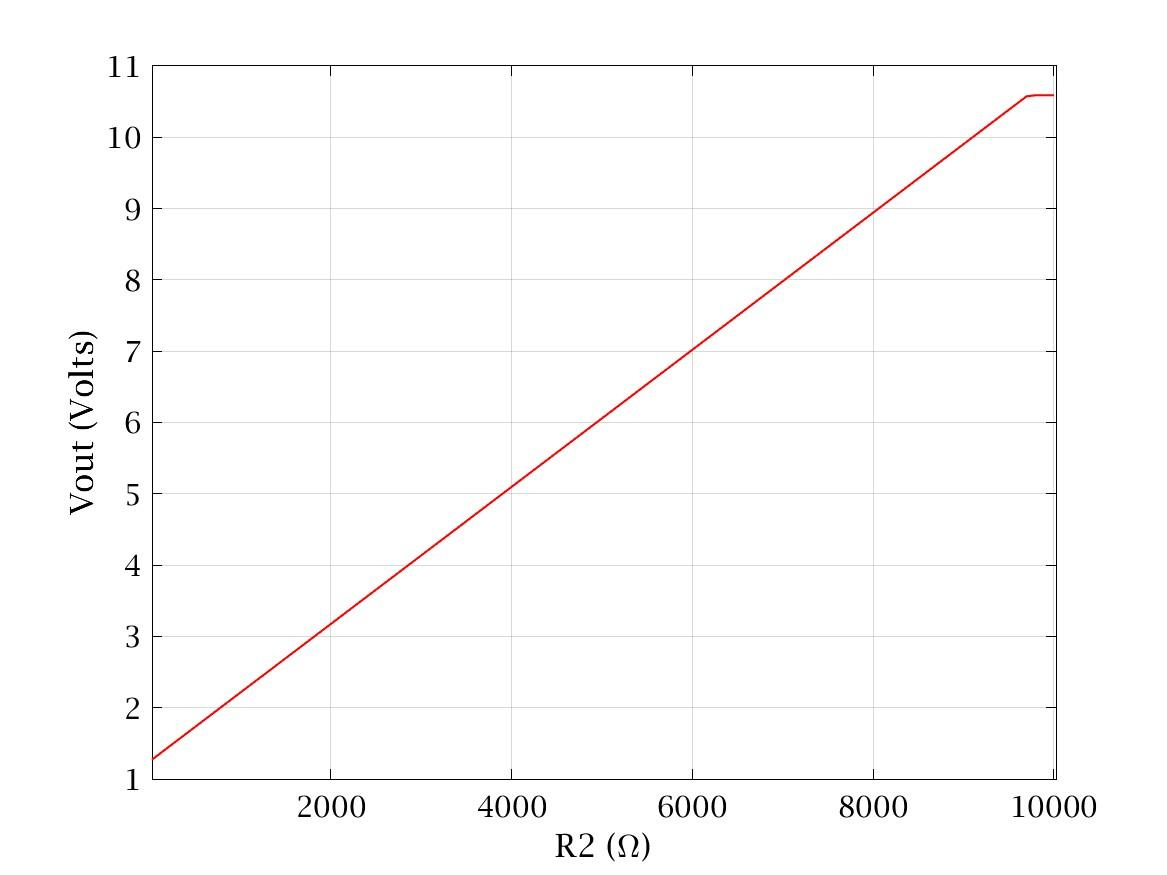

        Figure 6. Output voltage vs. value of R2 modeled with measured and optimized R1.

**The optimal value of R1 = _______ **$\Omega$. 

## Prototyping the circuit

NOTE: Adding R3 = 100$\Omega$ (in Fig. 7) in series with Vin ~ 12V is a reasonable extra precaution -- it will limit current in the event you misswire a short. But remember to remove it after verifying the circuit is working.

I was able to approximate the optimal R1 using two resistors in series (or 3 in parallel, I choose the former). If you find this too inconvenient, your kit has some 10k trimpots (potentiometers that require a screwdriver to adjust). You should still use a fixed 200 ohm resistor in series with the pot to ensure a minimum value of 200 ohms. Set R2 to almost maximum, and adjust the trim pot to VMAX. 

I also added a 1k resistor in series with an LED across the output to see if the LED reacted as expected. The DVM was connected to the output using clip leads so my hands were free (Fig. 7). 

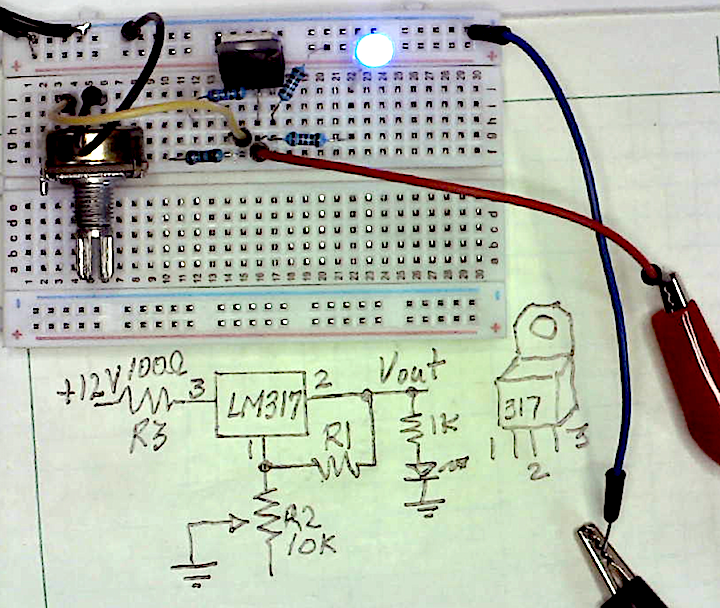

        Figure 7. Schematic and solderless breadboard construction using 2 series resistors for R1 and clip leads to the DVM (off to the right). 

What is the minimum voltage? __________ The maximimum voltage = ____________. Troubleshoot until you measure values around 1.25V and 11V respectively. Then remember to remove the 100 ohm input resistor when you're confident the circuit is working, and remeasure the maximum voltage.

Note: I forgot to remove the 100 ohm resistor (of course!) ... and was puzzled why Vmax was ~10.4V. It increased to >11V when the LED was removed, because the LED was drawing ~(11 - $V_f$)/1k ~ 9mA, so the voltage drop across the 100ohm resistor was V = iR ~ 0.9V. A common problem in making systems more reliable is that it usually adds complexity, which in this case isn't just an additional component, but also an extra "failure mode" that you forget to remove it. We often try to make systems "idiot proof", but "there's always a better idiot" to break them. Was the probability of miswiring the LM317 and saving it with the 100 ohm R3 greater than the probablilty of forgetting to remove R3 and wasting time troubleshooting why Vdropout was too large?

### Comparing circuit and model

Once resistors are connected in a circuit, it can be challenging to measure their resistance. To do so, always make certain the circuit power is off and large capacitors are discharged -- the only power source should be the ohmmeter itself. A challenge with measuring R1 between pins 1 and 2 of the LM317 (Fig. 7) is we don't know what parallel resistive path might be *inside* of the LM317. Safest is to measure R's after you open their circuits, but if that's inconvenient, then at least measure them and reverse the polarity. If you get the same answer both ways, it's more likely correct (or at least there are only other resistors in parallel). 

We've chosen R1 such that turning R2 changes the voltage throughout its entire possible range. How closely do the circuit and model agree? Let's measure what we can and compare. `Vdropout` is the difference between Vin and Vout, and `Vref` is the voltage between LM317 pins 1 and 2. Then power down the circuit before switching the DVM to ohms, and measure each resistance. Here are my values, but substitute yours.V

R1 = 1.355e3; % ohms 
Vin = 12.00; % measured 
VoutMin = 1.255; % volts measured
VoutMax = 10.79; % measured
Vref = 1.259; % measured  VERY carefully between LM317 pins 1 & 2
R2 = 11e3; % ohms maximum, with a lot of uncertainty because it was in circuit
VoutModeled = Vref*(1+R2/R1);
err = (VoutMax-VoutModeled)/VoutMax * 100;
fprintf('measured vmax = %.2f, modeled vmax = %.2f, err = %.2f%%\n', ...
    VoutMax, VoutModeled, err)

measured vmax = 10.79, modeled vmax = 11.48, err = -6.39%


My model and measurements agree within 4%. Might putting back the "neglected" IADJ*R2 improve the model? The datasheet specifies IADJ between 50-100uA, so this would change the prediction to between:

Vout2 = VoutModeled+[50 100]*1e-6*R2

Vout2 =    12.0297   12.5797


Suggests if IADJ were a little less than 50uA, the model and measurements would exactly agree. 

### Further embellishments

Capacitors: The datasheet recommends capacitors across the inputs and outputs, e.g., Fig. 8 C1. Their values aren't critical, although too much C3 on the output can result in the power supply slowly responding to changes in R2. We'll discuss capacitors later, but one way to think of these is that they add inertia against changing voltages. Sudden changes in input or load (what's connected to Vout) are "buffered" by the C's.  Otherwise it is possible for the device to oscillate under certain load conditions -- flipping between overshooting the voltage and then overcorrecting and undershooting. To measure any such oscillation, set your DVM to VAC or mVAC. You should only see mV of signal when you're turning the R2 pot very quickly. 

Switch: We'll want a convenient way to turn the power supply on and off. Your toolbox should contain a "double pole double throw" (DPDT) switch, which were cheaper than a single pole single throw (SPST) that we need, but some extra terminals may provide mechanical support. Recently I found a cheap source of 10k pots combined with a SPST switch. The contacts are more compact requiring a little more care soldering.

Voltmeter: To free up our DMM for measuring other things, we'll add a 3 digit voltmeter to give our power supply its own display. The voltmeter came in a small bag, and has 3 colored wires to connect to Vin, Vout, and ground. Which is which? Ground is usually black in color. Vin is likely red and Vout (the voltage to be measured) white or yellow. Try those colors on your solderless breadboard, to be extra safe, you could add 100 ohm resistors in series -- if you get the polarity wrong, the 100 ohms will limit current. 

Feet: It's a good idea to elevate the bottom side of a circuit board. It protects the desk or surface you're working on from scratches, and also reduces the chance of breaking solder connections -- which can become time consuming to debug. Usually one uses adhesive "feet", but we'll use what we have -- LEDs, unconventionally mounted *underneath* the 4 corners of the board. And we'll want them to illuminate as indicators that the power supply is turned on (of course!). 

**Assessment:** Why are the 4 feet wired in series? What would happen if they were connected in parallel?

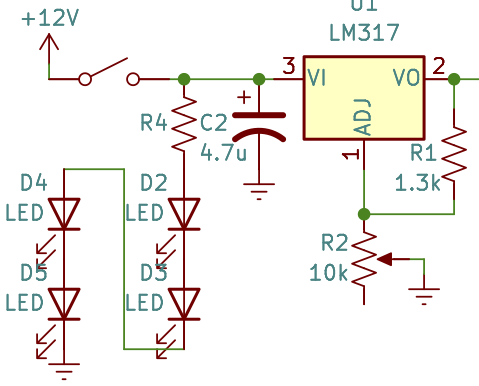

        Figure 8. Final schematic of our power supply board. Solder a black jumper wire to ground and a red one to VOut. 

**Assessment:** Make sure you understand everything about Fig. 8. Compute and justify the value of R4.

## Soldering the circuit

Solderless breadboards make it quick and easy to change components and wiring. But their connections are not very reliable nor durable. Ideally, in any professional environment, you would leave the breadboard intact and solder another copy of the circuit on a circuit board. That way if the soldered circuit exhibits unexpected behavior, you can compare it to the working breadboard. Unfortunately, we don't have the duplicate components to do this, so you'll have to disassemble your circuit part by part and reassemble it with solder. 

### Layout

A useful first step is to sketch a wiring diagram. Unlike the schematic (Fig. 8), who's purpose is to most clearly show the components and interconnections conveying *function*, the wiring diagram's goal is to display *form* or the physical (geometrically accurate) layout. In layout, we have to realize the details of how R1 is made, i.e., one or 2 (or more) fixed R's or a trimpot, ... We also have to respect the physical order of the LM317 pins (1,2,3) from left to right, vs. their functional order in Fig. 8, conventionally with current and signal flowing left to right and/or top to bottom. 

And consider the big picture, where will future projects fit, to manage our board's 4"x6" real estate and ergonomics. I suggest following the approximate layout of Fig. 9, compactly building the power supply in the bottom left corner. 

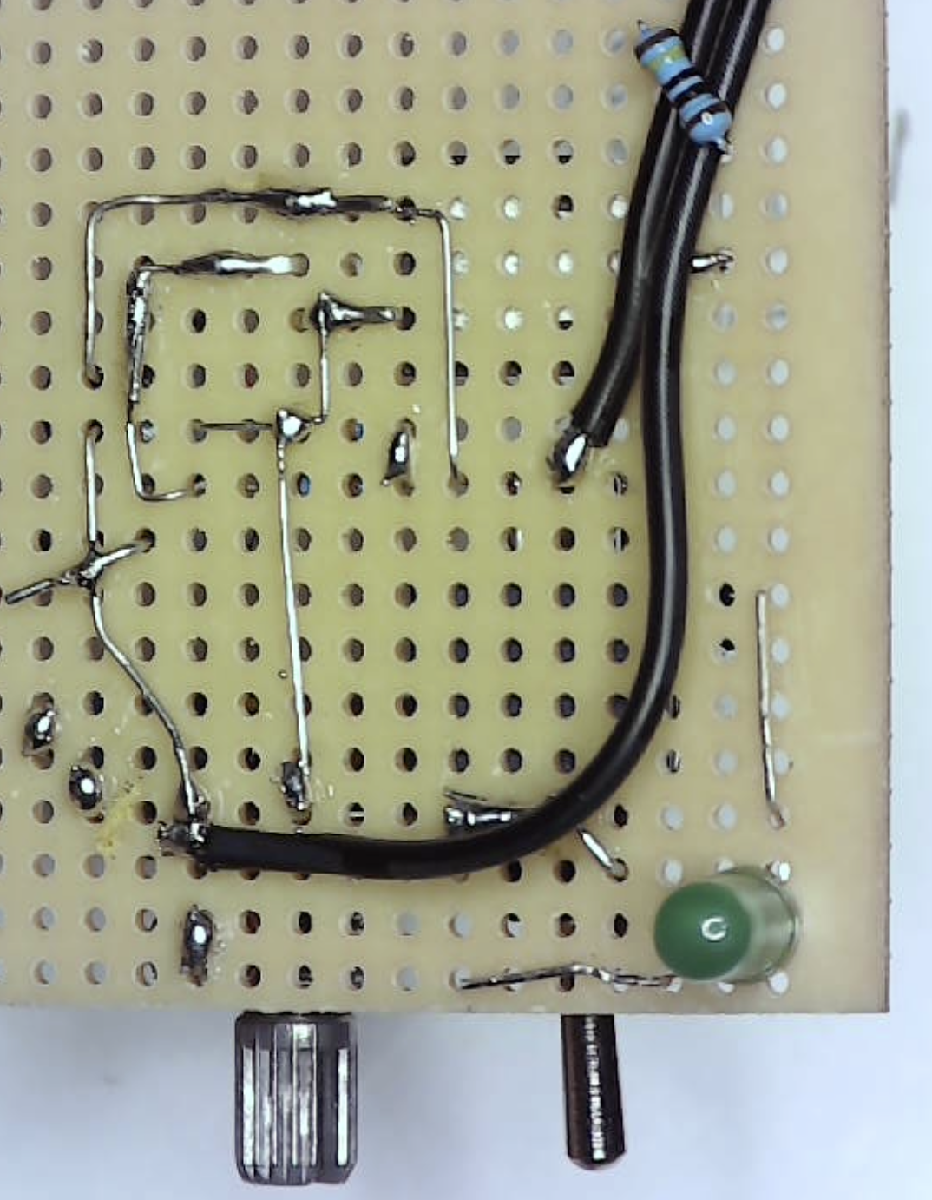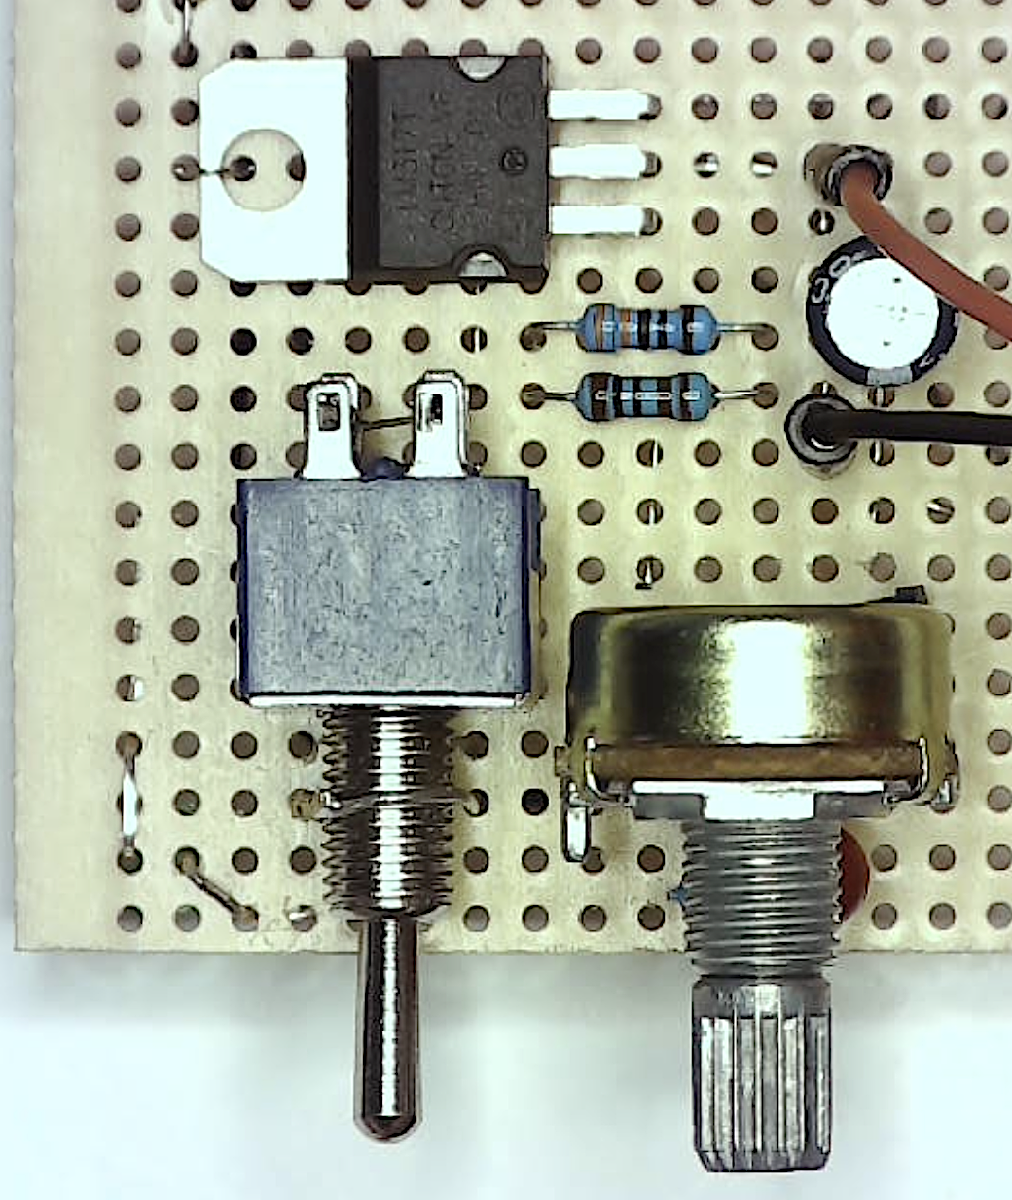 

        Figure 9. A compact layout of the power supply in the bottom right corner of your board. 

- Ergonomics should play a big factor in placing user controls like switches and pots. The pot (R2) and switch are mechanically protected by the board if they're not hanging too far out, but far enough to be convenient to operate. 

- Leave space in the corners for the feet (or install them first?). 

- Leaving a little free space can facilitate possible future revisions.

- Place parts close to use their lead wires for interconnections wherever possible.

- Avoid overlapping (requiring insulation) wires whereever possible.

- Keep the wiring as flat and close to the board as possible.

- The LM317 is most stable mechanically if its leads are bent 90 degrees so the (flat) body rests on the board. Your long-nose plier is ideal for achieving this gentle bend.  

- R1 consists in this photo of the two fixed resistors above R2. 

- Sacrificial resistor wires were soldered to the switch directed downward before placing the switch on the board (and tying its shaft with a loop of wire for additional mechanical support. 

- Solder is a weak metal and should not generally be relied upon for mechanical stability. Power and any other wires coming onto or off a board should include a "strain relief" so a moderate accidental yank on the cord won't be transmitted to the more fragile circuit. The resistor on the top in Fig. 9 has been hijacked for this purpose. It's not connected to anything on the other side of the board but itself, squeezing the power cable against the board. 

- Use your long-nose pliers to loop the LED feet leads through the holes tightly, so they stay flat and flush. Consider their polarity so they all point clockwise or counterclockwise to facilitate wiring. Explain your choice of value for R4. __________

- A sacrificial LED was wedged under the stem of R2 for mechanical support, along with a capacitor or LED wedged under R2's back side -- to keep the pot from rocking front to back, which would eventually fatigue its leads leading to one or more breaking.

## Final testing, debugging, validation

If your power supply isn't working, then apply reductionism to debug it. Does voltage get through the switch to pin 3? Is R2 grounded? ... 

Explain how you know the power supply is working. Here are some tests: 

- Min and max voltages are ~1.25V and ~11V respectively.

- The 3 digit voltmeter reads comparable to your DMM. Expect some discrepancies -- you're comparing a $1 meter to a $25 meter. 

- Switch turns on and off the power supply, display, and LED feet. 

- Pot R2 is roughly linear (i.e., at middle position, Vout ~6V), saturates at Vmax just before its maximum rotation. 

- Load test: Measure $R_{Thevenin}$ for the power supply, by setting the voltage $\sim$10V and measure how it changes upon connecting a 100$\Omega$ load resistor. Note, don't leave the resistor connected for long, it will burn up. Use a tool to remove it so you don't burn your fingers (or table). $R_{Thevenin}$ = ___________. 

- ...

## Reflections

Experiments and simulations: We've built two things here: a circuit around an LM317 voltage regulator that produces 1.2-11VDC controlled by a potentiometer, and a MATLAB model. The model was tweaked so its numerical results agree with measurements of the circuit within the DVM's experimental error. Although you've compared theory and experiment is most of your previous physics experiments, our modeling here exhibits a few differences. First, the model guided the design of the apparatus (e.g., suggested initial values of R1), and the apparatus guided design of the model (e.g., confirmed IADJ*R2 was not very insignificant). This "bootstrapping" of theory and experiment is common in both science and engineering. Theory and experiment work like pushing and pulling a shovel into the ground while applying pressure. Is it better to push or pull? You dig by alternating the two -- preferring one doesn't advance you nearly as much as using both. 

Some students found their power supplies range of voltages was limited to ~4-9V, and further investigation showed this occured when their 10k$\Omega$ trimpot that was part of R1 was near its maximum resistance. Reducing R1 resulted in normal operation. Failure of agreement between mathematical models and reality give us an opportunity to explore our mental models and try to discover why the mathematical model failed. 

How *does* the LM317 work? How does a car work? "You start it by turning a key or pushing a button, put it in Drive, and press on the accelerator pedal ..." is analogous to "you put R1 between pins 1 and 2, and R2 from pin 1 to ground, and Vout = 1.25*(1+R2/R1)...". Let's inquire deeper, I figured this out by carefully studying the datasheet.

 

Vout = VREF (1 + R2/R1) + IADJ R2 

        Figure 3. The LM317 basic circuit and it's characteristic equation. 

The LM317 generates a constant reference voltage of $V_{REF}$ = 1.25V between its Output and Adj pins (Fig. 3). R1 converts $V_{REF}$ into a current: $i_1 = V_{REF} / R1$~ 1mA in our case. Where does this current go? $i_1+I_{ADJ}$ have only one path: through the pot R2 to ground, converting it into a voltage across R2 (to ground) of $V_{R2} = (i_1+I_{ADJ}) * R2$. $V_{out} = V_{R2} + V_{REF}$, with a little algebra, gives the characteristic equation in Fig. 3. We'll revisit the theory of operation later when we learn how to control the LM317 voltage with a microcontroller and MATLAB. This tells us $I_{ADJ}$ can be ignored if it's << $I_1$. In the datasheet, $I_1 = 1.25V/240\Omega \approx 5mA$which met this condition. Our $I_1 \approx 1mA$ is 5 times smaller, so we should be more cautious ignoring $I_{ADJ}$. Our dropout model (`Vout2`) suggests $i_{ADJ} \le50\mu A <<1mA$, so the assumption is still true.

**Assessment: **Derive the characteristic equation, explaining each step.

Some more lessons learned

- Tricks to parse datasheets -- like a phone book, you don't read it cover-to-cover.

- Start simple and build complexity as necessary, in small steps.

- Schematic diagrams attempt to convey the function and logic of the circuit. Thus generally inputs are on the left, outputs on the right. A separate wiring diagram is often useful to help you physically place and connect the parts, with minimal extraneous and crossing wires. Don't try to meet both goals in one diagram, and don't assume the physical pins are located as in a schematic. E.g., in the schematics shown here, the LM317 pins are in order 3,1,2 because that reflects the functional current flow through the circuit. 

- The component values you use are the ones that you have -- "optimal" can mean "what I have now".

- When using a pot or variable resistor, a fixed resistor in series maybe prudent to set Rminimum  = R_fixed.

- When building a circuit, double check each connection between schematic and circuit before powering up. Ohmmeter in beep mode can be useful.

- Think about what you're going to measure that will tell you whether the circuit is working, and set up your measurement before applying power. 

- After applying power, feel components for excess heat and look (sniff) for smoke. 

- What other important reflectious and lessons learned can you add to your lab report?

### Lab report

Consider your audience: your professor or your boss in a company. They (presumably) know more than you about the objective, theory, applications, etc. What they don't know is what you did. The purpose of the report is to demonstrate what you did. 

- Objective should be clearly stated -- one sentence is often enough to convey whether you're on the same page with your goals.

- Methods show how you reduced implementing the Objective to sub-tasks. It includes source codes to acquire data, formulas to reduce data to Results, schematics of circuits you built (make your own drawings, don't just photocopy mine). Most importantly to the reader, the Methods conveys that you understand the protocol. Don't tell the reader how they can/should repeat the experiment, but provide enough detail so if they question your data or Results, they can understand how it came to to be.

- Results are what the Methods generated. There may not be a lot to say in Results, because the data "speaks" for itself. If the Results are more than a few numerical values, consider representing them graphically, or with statistics (e.g., mean ± standard deviation, slope, etc.). If the raw data is voluminous, include it in copy/pasteable tabular form in Appendices, or a separate file that's easy for the boss to analyze. All figures should be sequentially numbered and contain short descriptive captions.

-  Discussion is where you interpret or attribute meaning to the Results. E.g., if you measured power consumption of your LED nightlight at <.1kWh/month ~ $0.05/month (i.e., those are your Results), then the Discussion is where you  interpret how significant this is, i.e., not worthy of reducing, unless it is part of an apparatus that would be replicated in millions of homes. If the Results meet expectations, there may not be much to say. If they are dissonant, you may want to troubleshoot and verify the Methods, and repeat for new Results. I generally don't publish my mistakes (and I make a lot of them), and suggest you do the same. If you can't generate reasonable Results after multiple attempts and consultation with peers and others, then the Discussion is an opportunity to hypothesize about why. Hopefully you'll realize new Methods for testing some of those new hypotheses, and new Results will let you rule out some hypotheses. If you choose to include some of these experiments in your report, then revise the Methods, Results, and Discussion to include their coherent descriptions. Labs are thus (often) not "linear", but can be iterative processes. 

- Conclusions. I often mix Conclusions within Discussion, as part of the critical analyses of the Results. Briefly summarize what you learned from the activity. State your key insights about the processes, and about the physics. Open questions, ideas for improving the experiment, demonstrate your understanding at meta-levels of the activity. 

### Problems

- If you use your power supply for 10 hours/week (right??), and it uses ~10mA  at ~12V, then over the semester it will have consumed how many watt-hours of electricity, which at ~$.25/kWh would cost how much? (Answers: ~20 watt-hours and ~1/2 cents).

- Assume you have a 24V DC adapter and a 10k pot for R2. The ideal value for R1 = ________ $\Omega$.

## References

[https://en.wikipedia.org/wiki/LM317](https://en.wikipedia.org/wiki/LM317)

[https://www.st.com/resource/en/datasheet/lm317.pdf](https://www.st.com/resource/en/datasheet/lm317.pdf) 